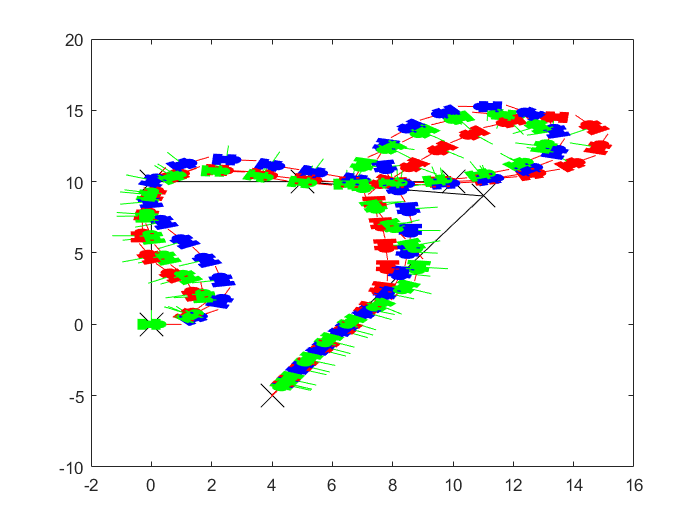

unicycle = unicycleKinematics("VehicleInputs","VehicleSpeedHeadingRate");

diffDrive = differentialDriveKinematics("VehicleInputs","VehicleSpeedHeadingRate");

diffDrive.WheelSpeedRange = [-10 10]*2*pi;

bicycle = bicycleKinematics("VehicleInputs","VehicleSpeedHeadingRate","MaxSteeringAngle",pi/8);

carLike = ackermannKinematics;

waypoints = [0 0; 0 10; 10 10; 5 10; 11 9; 4 -5];
% Define the total time and the sample rate
sampleTime = 0.05;               % Sample time [s]
tVec = 0:sampleTime:20;          % Time array

initPose = [waypoints(1,:)'; 0]; % Initial pose (x y theta)

% Define a controller. Each robot requires its own controller
controller1 = controllerPurePursuit("Waypoints",waypoints,"DesiredLinearVelocity",3,"MaxAngularVelocity",3*pi);
controller2 = controllerPurePursuit("Waypoints",waypoints,"DesiredLinearVelocity",3,"MaxAngularVelocity",3*pi);
controller3 = controllerPurePursuit("Waypoints",waypoints,"DesiredLinearVelocity",3,"MaxAngularVelocity",3*pi);

goalPoints = waypoints(end,:)';
goalRadius = 1;

% Compute trajectories for each kinematic model under motion control
[tUnicycle,unicyclePose] = ode45(@(t,y)derivative(unicycle,y,exampleHelperMobileRobotController(controller1,y,goalPoints,goalRadius)),tVec,initPose);
[tBicycle,bicyclePose] = ode45(@(t,y)derivative(bicycle,y,exampleHelperMobileRobotController(controller2,y,goalPoints,goalRadius)),tVec,initPose);
[tDiffDrive,diffDrivePose] = ode45(@(t,y)derivative(diffDrive,y,exampleHelperMobileRobotController(controller3,y,goalPoints,goalRadius)),tVec,initPose);
unicycleTranslations = [unicyclePose(:,1:2) zeros(length(unicyclePose),1)];
unicycleRot = axang2quat([repmat([0 0 1],length(unicyclePose),1) unicyclePose(:,3)]);

bicycleTranslations = [bicyclePose(:,1:2) zeros(length(bicyclePose),1)];
bicycleRot = axang2quat([repmat([0 0 1],length(bicyclePose),1) bicyclePose(:,3)]);

diffDriveTranslations = [diffDrivePose(:,1:2) zeros(length(diffDrivePose),1)];
diffDriveRot = axang2quat([repmat([0 0 1],length(diffDrivePose),1) diffDrivePose(:,3)]);

figure
plot(waypoints(:,1),waypoints(:,2),"kx-","MarkerSize",20);
hold all
plotTransforms(unicycleTranslations(1:10:end,:),unicycleRot(1:10:end,:),'MeshFilePath','groundvehicle.stl',"MeshColor","r");
plotTransforms(bicycleTranslations(1:10:end,:),bicycleRot(1:10:end,:),'MeshFilePath','groundvehicle.stl',"MeshColor","b");
plotTransforms(diffDriveTranslations(1:10:end,:),diffDriveRot(1:10:end,:),'MeshFilePath','groundvehicle.stl',"MeshColor","g");
view(0,90)